# EE525 Project 4

Author: Grant Gallagher

Date: 11/20/2021

Use MATLAB to implement a Kalman filter that tracks a moving target. The dataset is 2D (X,Y) measurement data of the position of a US Navy ship over a span of approximately eight minutes. Set up a Kalman filter with  a  [position_X,  velocity_X,  position_Y,  velocity_Y]  state.  The Kalman filter should function in ‘realtime’ – that is processing should occur as the measurements are read. Experiment with the filter parameters, and study their effects on tracking performance. 

Submit the following:

-  A report documenting the set up and implementation of the filter, plots  of  the  raw  measurements  and  filtered  signal,  the  problems you  encountered,  analysis  and  discussion  of  the  results.  Also include your effort in “tweaking” the filter parameters (55 points).

- Well-documented  source  code.  If  more  than  one  function/file  is  used, provide detailed description as to how to run it (25 points). 

- Repeat 1-2 for an additional dataset. It is a 3D (X,Y,Z) measurement data of the position of a US Navy submarine over a span of approximately two minutes (20 points).  

Clear Console

clc
clear

Import the Data

varNames = {'Time','North','East'};
varTypes = {'datetime','double','double'};
ship_data = importShipData('2Ddata.txt',varNames,varTypes)

ship_data = 458×3 table
        Time        North    East 
    ____________    _____    _____

    14:21:19.655    58259    87671
    14:21:20.655    58261    87673
    14:21:21.655    58264    87674
    14:21:22.655    58265    87674
    14:21:23.655    58265    87674
    14:21:24.655    58267    87675
    14:21:25.655    58269    87674
    14:21:26.655    58270    87674
    14:21:27.655    58272    87674
    14:21:28.655    58273    87674
    14:21:29.655    58274    87675
    14:21:30.655    58276    87675
    14:21:31.655    58276    87675
    14:21:32.655    58277    87676
    14:21:33.655    58279    87676
    14:21:34.654    58280    87676



stateVarNames = {'Time','X_North','V_North','X_East','V_East'};
stateVarTypes = {'datetime','double','double','double','double'};
filtered_data = table('Size',[height(ship_data) length(stateVarNames)],'VariableTypes',stateVarTypes,'VariableNames',stateVarNames)

filtered_data = 458×5 table
    Time    X_North    V_North    X_East    V_East
    ____    _______    _______    ______    ______

    NaT        0          0         0         0   
    NaT        0          0         0         0   
    NaT        0          0         0         0   
    NaT        0          0         0         0   
    NaT        0          0         0         0   
    NaT        0          0         0         0   
    NaT        0          0         0         0   
    NaT        0          0         0         0   
    NaT        0          0         0         0   
    NaT        0          0         0         0   
    NaT        0          0         0         0   
    NaT        0          0         0         0   
    NaT        0          0         0         0   
    NaT        0          0         

Define State Space Matrix


$$x=x_0 +\dot{x} \Delta t+\frac{1}{2}\ddot{x} {\Delta t}^2$$



$$\left\lbrack \begin{array}{c}
x\\
\dot{x} \\
y\\
\dot{y} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cccc}
1 & \Delta t & 0 & 0\\
0 & 1 & 0 & 0\\
0 & 0 & 1 & \Delta t\\
0 & 0 & 0 & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x\\
\dot{x} \\
y\\
\dot{y} 
\end{array}\right\rbrack$$


Initial Estimates for ${{\hat{x} }_k }^-$ and its error covariance ${P_k }^-$.

dt = 1;
x_pos = 87000;
x_vel = 2;
y_pos = 87000;
y_vel = 2;

x_hat_prev = [x_pos;
              x_vel;
              y_pos;
              y_vel];
n = length(x_hat_prev); % Order of the system
P_prev = eye(n);

Declare Matrices

dt = 1; % Initial timestep
phi = [1 dt 0  0; % State Transition Matrix
       0  1 0  0;
       0  0 1 dt;
       0  0 0  1];
H = eye(n); % Measurement Matrix

Q = eye(n)*1e-6;
R = eye(n)*0.01;

Predicted Values

for k = 1:400
    %% --- Measurement Update ("Correct") ---
    % (1) Compute Kalman gain
    K = P_prev*H'*inv(H*P_prev*H'+R)';
    
    % (2) Update estimate with measurement z_k 
    % Store old ship data values
    if k > 1
        time_old = time;
    end
    x_pos_old = x_pos;
    y_pos_old = y_pos;
    
    % Read new ship data values
    [time, x_pos, y_pos] = readShipData(ship_data, k);
    
    % Calculate derivative values
    if k > 1
        dt = datenum(time-time_old)*60*60*24;
    end
    x_vel_new = (x_pos-x_pos_old)/dt;
    y_vel_new = (y_pos-y_pos_old)/dt;
    
    x = [x_pos;
         x_vel;
         y_pos;
         y_vel];
     
    z = H*x;
    
    
    x_hat = x_hat_prev+K*(z-H*x_hat_prev);
    
    % (3) Update the error covariance
    P = (eye(n)-K*H)*P_prev;
   
    
    %% --- Time update ("Predict") ---
    % (1) Project the state ahead
    x_hat_new = phi*x_hat;  
    
    x_hat_prev = x_hat_new;
    % (2) Project the error covariance ahead
    P_new = phi*P*phi'+Q;
    P_prev = P_new;
    
    % (3*) Store filtered data
    filtered_data(k,2:end) = array2table(x_hat_new');
    filtered_data.Time(k) = time;
    filtered_data.Time.Format = 'HH:mm:ss.SSS';
end

Convert Data to table outputs

filtered_data

filtered_data = 458×5 table
        Time        X_North    V_North    X_East    V_East 
    ____________    _______    _______    ______    _______

    14:21:19.655     58546           2    87666           2
    14:21:20.655     58320     -54.906    87674      3.3286
    14:21:21.655     58247     -54.852    87677      3.1321
    14:21:22.655     58220     -45.539    87678       2.556
    14:21:23.655     58211     -36.362    87678      2.0234
    14:21:24.655     58210     -28.763    87678      1.7104
    14:21:25.655     58214     -22.863    87678      1.3439
    14:21:26.655     58218     -18.411    87678      1.0774
    14:21:27.655     58223      -14.96    87677     0.87952
    14:21:28.655     58227     -12.309    87677     0.72948
    14:21:29.655     58232     -10.236    87677     0.65518
    14:21:30.655     

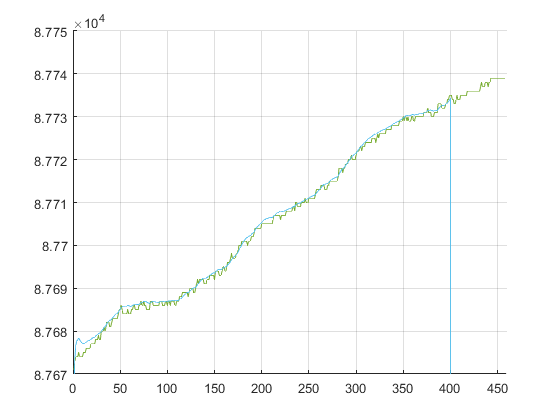

fig2 = figure(2);
hold on
plot(ship_data.East)
plot(filtered_data.X_East)
hold off
grid on
xlim([0 460])
ylim([87670 87750])

## Import Data

function dataTable = importShipData(fileName,varNames,varTypes)
    delimiter = '\t';        % Horizontal tab delimiter
    dataStartLine = 8;       % Start on 8th line
    extraColRule = 'ignore'; % Ignore extra columns
    opts = delimitedTextImportOptions('VariableNames',varNames,...
                                    'VariableTypes',varTypes,...
                                    'Delimiter',delimiter,...
                                    'DataLines', dataStartLine,...
                                    'ExtraColumnsRule',extraColRule);
    opts = setvaropts(opts,'Time','InputFormat','HH:mm:ss.SSS'); % Set datetime format
    dataTable = readtable(fileName, opts); % Return the ship data as a table
    dataTable = rmmissing(dataTable,1); % Remove invalid data
    % dataTable.Time = datenum(dataTable.Time); % Convert datetime to serial date number
    
    % Output
    % dataTable.Time = (dataTable.Time - dataTable.Time(1)) * 60 * 60 * 24 + 1; % Convert time to seconds
end

## Read Ship Data

function [time, x_pos, y_pos] = readShipData(ship_data_raw, k)
    time = table2array(ship_data_raw(k,1));
    x_pos = table2array(ship_data_raw(k,2));
    y_pos = table2array(ship_data_raw(k,3));
end

## Van Loan Method

function [phi, Q] = vanLoan(F,G,W,dt)
    % Calculate the size of the system
    n = length(F);
    
    % Determine A and B matrices
    A = [ -F       G*W*G';
          zeros(n)     F']*dt;
    B = expm(A);
    
    % Calculate phi and Q
    phi = B(n+1:end,n+1:end)';
    Q = phi*B(1:n,n+1:end);
end